# **Matlab案例代码解析**

## 1. 基础函数使用案例

### 1.3 知乎提问

#### 1.3.3 计算心形线的面积

颜值即正义；

**颜色模板参考：**[**60套优雅的颜色模板**](https://zhuanlan.zhihu.com/p/444970597)

# 如何用matlab求下图的面积?

如图，如何用matlab求右上角心形的面积，其表达式如下。

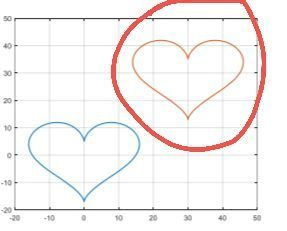

原问题：[https://www.zhihu.com/question/532429003/answer/2542275689](https://www.zhihu.com/question/532429003/answer/2542275689)

clear;clc;
t = linspace(0, pi, 1000);
x = 16 * sin(t) .^ 3 + 30;
y = 13 * cos(t) - 5*cos(2*t) - 2 * cos(3*t) - cos(4*t) + 30;
% 方法一：积分
% 确定最右边点位置
[xmax, idx] = max(x);
% 把线分成两部分
x1 = x(1:idx);
y1 = y(1:idx);
x2 = x(idx+1:end);
y2 = y(idx+1:end);
% 我们再把这两部分插值成相同份数
N = 10000;
xx = linspace(30, xmax, N);
yy1 = interp1(x1, y1, xx);
% 逆序
yy2 = interp1(x2(end:-1:1), y2(end:-1:1), xx);
plot(xx, yy1, 'LineWidth', 2);
hold on
plot(xx, yy2, 'LineWidth', 2);
% 用积分求面积：梯形公式
dx = xx(2) - xx(1);
S1 = 0;
for i = 1:N-1
    S1 = S1 + 0.5 * dx * (yy1(i) - yy2(i) + yy1(i +1) - yy2(i+1));
end
disp(S1);

  282.7423


% 方法二：三角形面积
S2 = polyarea(x,y)

S2 = 282.7424

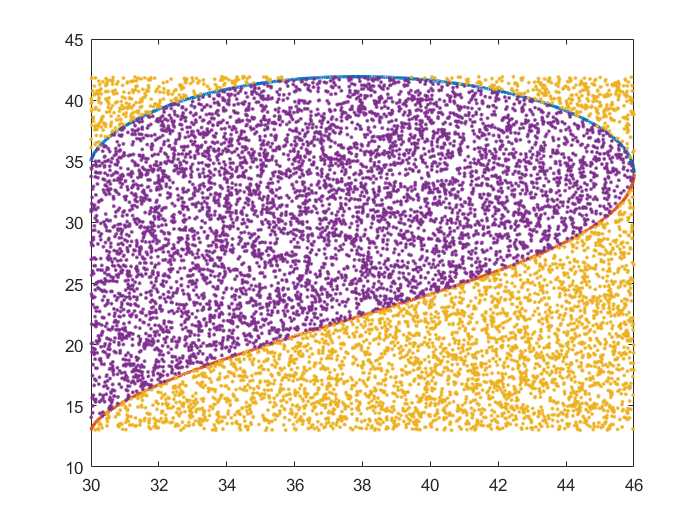

% 方法三：蒙特卡洛
% 确定边界
xmin = 30;
xmax = max(x);
ymin = min(y);
ymax = max(y);
% 在此范围内随机生成大量点 判断落在范围内的点
x_rand = (xmax - xmin)*rand(N,1) + xmin;
y_rand = (ymax - ymin)*rand(N, 1) + ymin;
plot(x_rand, y_rand, '.');
% 确定这些点对应的边界
y_min = interp1(xx, yy2, x_rand);
y_max = interp1(xx, yy1, x_rand);
idx = (y_rand > y_min) & (y_rand < y_max);
plot(x_rand(idx), y_rand(idx), '.');
hold off;

S3 = (ymax - ymin)*(xmax - xmin) * sum(idx) / N

S3 = 282.4749